clear all;

limits = [1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 12, 14, 16, 18, 20, 25, 35, 45, 60, 75, 100, 125, 150, 175, 200, 225, 250, 275, 300, 325, 350, 375, 400, 425, 450, 475, 500];

n_cells = 64;

clock_freq = 1e8;

start_index = 1;
end_index = 10000;
n_sample = end_index - start_index + 1;

## RO cell

prefix="ro_count_limit";
ro_cells_averages = zeros(n_cells, length(limits));

for i=1:length(limits)
    data = readmatrix(prefix+'_'+string(limits(i))+'.csv');
    for j=1:n_cells
        ro_cells_averages(j,i) = mean(data(start_index:end_index,j));
    end
end

### Average cells oscillations

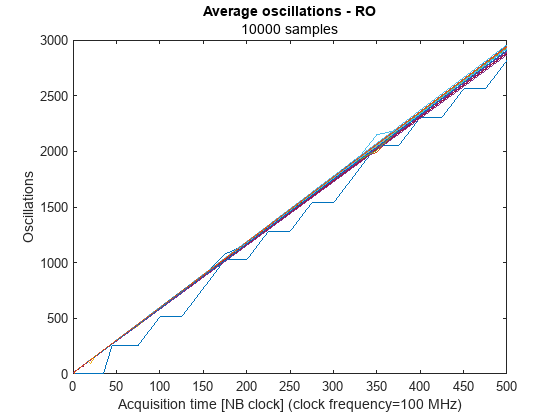

fig = figure;
for i=1:length(limits)
    plot(limits, ro_cells_averages(i,:));
    hold on;
end
title("Average oscillations - RO");
subtitle(string(n_sample)+" samples");
ylabel("Oscillations");
xlabel("Acquisition time [NB clock] (clock frequency="+string(clock_freq/1e6)+" MHz)");
saveas(fig, "RO_oscillations_vs_time_"+string(n_sample)+"_samples.png");

### Average cells oscillations (zoomed)

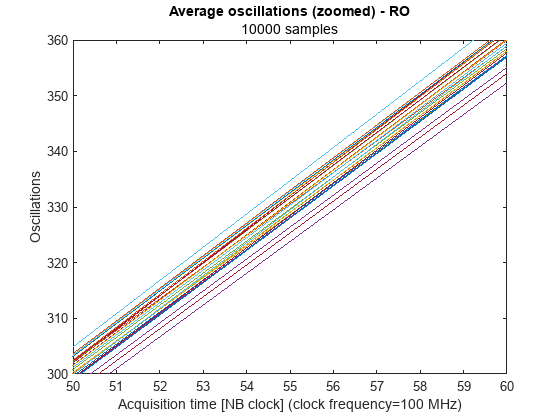

fig = figure;
for i=1:length(limits)
    plot(limits, ro_cells_averages(i,:));
    hold on;
end
subtitle(string(n_sample)+" samples");
ylabel("Oscillations");

xlabel("Acquisition time [NB clock] (clock frequency="+string(clock_freq/1e6)+" MHz)");
xlim([50 60]);
ylim([300 360]);
saveas(fig, "RO_oscillations_vs_time_zoomed_"+string(n_sample)+"_samples.png");

## TERO cell (4-LUT)

prefix="tero_4_count_limit";
tero_4_cells_averages = zeros(n_cells, length(limits));

for i=1:length(limits)
    data = readmatrix(prefix+'_'+string(limits(i))+'.csv');
    for j=1:n_cells
        tero_4_cells_averages(j,i) = mean(data(start_index:end_index,j));
    end
end

### Average cells oscillations

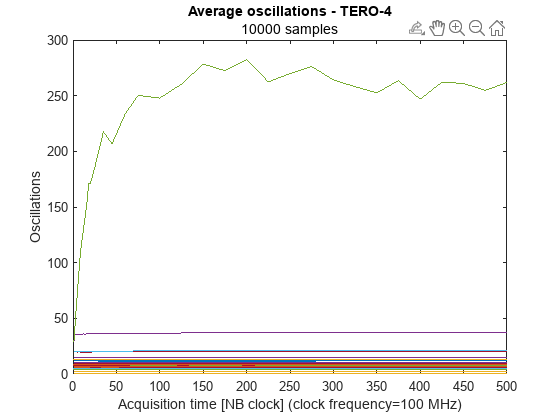

fig = figure;
for i=1:length(limits)
    plot(limits, tero_4_cells_averages(i,:));
    hold on;
end
subtitle(string(n_sample)+" samples");
ylabel("Oscillations");
xlabel("Acquisition time [NB clock] (clock frequency="+string(clock_freq/1e6)+" MHz)");
saveas(fig, "TERO_4_oscillations_vs_time_"+string(n_sample)+"_samples.png");

### Average cells oscillations (zoomed)

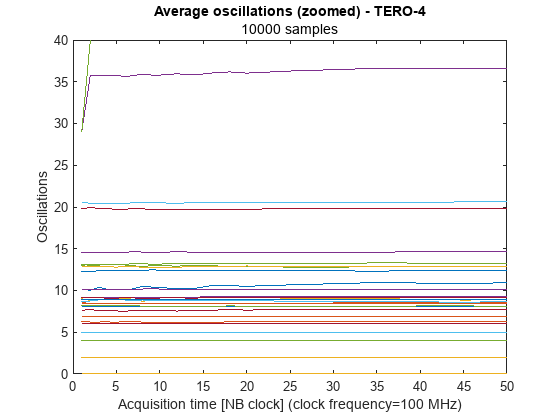

figure;
for i=1:length(limits)
    plot(limits, tero_4_cells_averages(i,:));
    hold on;
end
subtitle(string(n_sample)+" samples");
ylabel("Oscillations");
xlabel("Acquisition time [NB clock] (clock frequency="+string(clock_freq/1e6)+" MHz)");
xlim([0 50]);
ylim([0 40]);

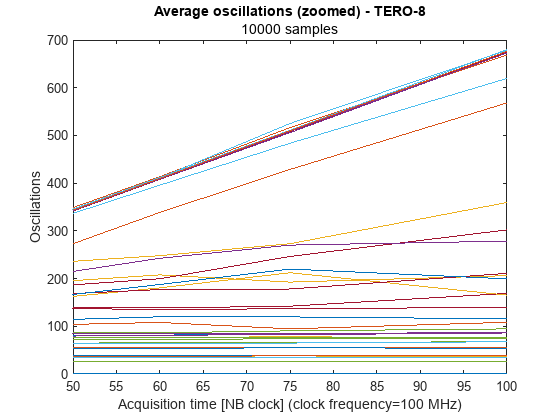

saveas(fig, "TERO_4_oscillations_vs_time_zoomed_"+string(n_sample)+"_samples.png");

## TERO cell (8-LUT)

prefix="tero_8_count_limit";
tero_8_cells_averages = zeros(n_cells, length(limits));

for i=1:length(limits)
    data = readmatrix(prefix+'_'+string(limits(i))+'.csv');
    for j=1:n_cells
        tero_8_cells_averages(j,i) = mean(data(start_index:end_index,j));
    end
end

### Average cells oscillations

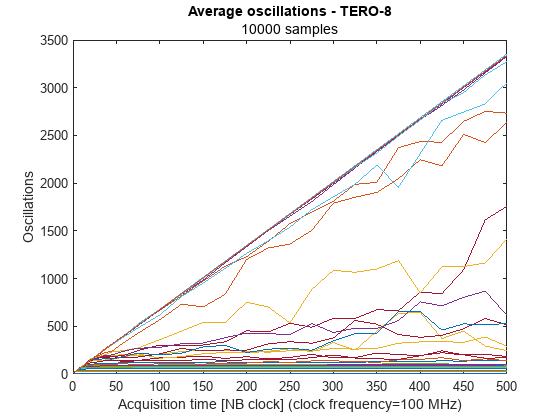

fig = figure;
for i=1:length(limits)
    plot(limits, tero_8_cells_averages(i,:));
    hold on;
end
subtitle(string(n_sample)+" samples");
ylabel("Oscillations");
xlabel("Acquisition time [NB clock] (clock frequency="+string(clock_freq/1e6)+" MHz)");
saveas(fig, "TERO_8_oscillations_vs_time_"+string(n_sample)+"_samples.png");

### Average cells oscillations (zoomed)

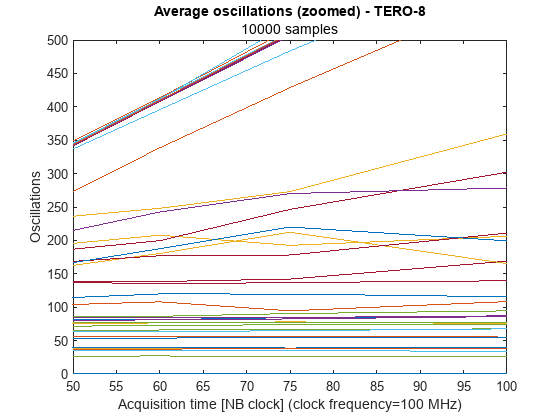

fig = figure;
for i=1:length(limits)
    plot(limits, tero_8_cells_averages(i,:));
    hold on;
end
subtitle(string(n_sample)+" samples");
ylabel("Oscillations");
xlabel("Acquisition time [NB clock] (clock frequency="+string(clock_freq/1e6)+" MHz)");
xlim([50 100]);
ylim([0 500]);
saveas(fig, "TERO_8_oscillations_vs_time_zoomed_"+string(n_sample)+"_samples.png");

### Average cells oscillations (zoomed)

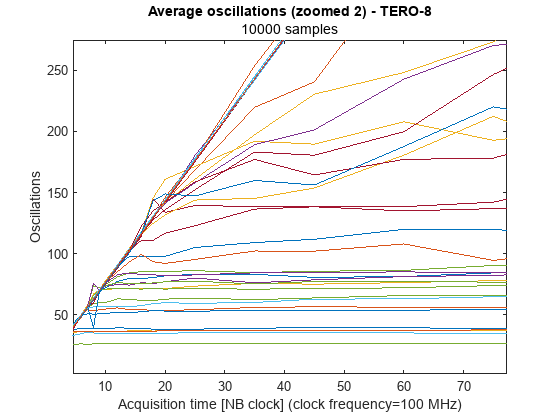

fig = figure;
for i=1:length(limits)
    plot(limits, tero_8_cells_averages(i,:));
    hold on;
end;
subtitle(string(n_sample)+" samples");
ylabel("Oscillations");
xlabel("Acquisition time [NB clock] (clock frequency="+string(clock_freq/1e6)+" MHz)");
xlim([0 80]);
ylim([0 300]);
saveas(fig, "TERO_8_oscillations_vs_time_zoomed_2_"+string(n_sample)+"_samples.png");